syms x
r = evalin(symengine,'series(x*exp(x),x=0,8)')

$$r = x+x^{2}+\frac{x^{3}}{2}+\frac{x^{4}}{6}+\frac{x^{5}}{24}+\frac{x^{6}}{120}+\frac{x^{7}}{720}+\frac{x^{8}}{5040}+O\left(x^{9}\right)$$

pretty(r)

          3    4    5     6     7     8
     2   x    x    x     x     x     x        9
x + x  + -- + -- + -- + --- + --- + ---- + O(x )
          2    6   24   120   720   5040



第二中代码

syms x
r = taylor(x*exp(x),x,'Order',9)

$$r = \frac{x^{8}}{5040}+\frac{x^{7}}{720}+\frac{x^{6}}{120}+\frac{x^{5}}{24}+\frac{x^{4}}{6}+\frac{x^{3}}{2}+x^{2}+x$$

pretty(r)

  8      7     6    5    4    3
 x      x     x    x    x    x     2
---- + --- + --- + -- + -- + -- + x  + x
5040   720   120   24    6    2



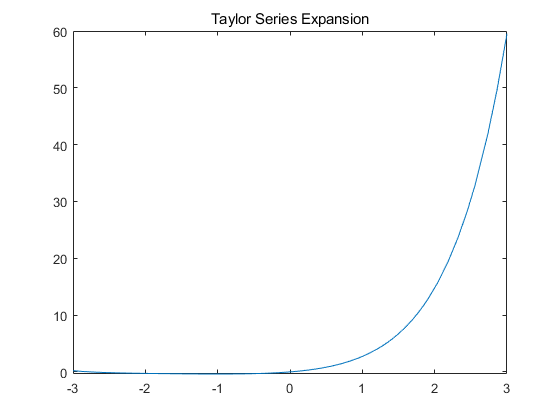

fplot(r)
xlim([-3 3])
title('Taylor Series Expansion')

A = gallery(5);A(:,1)= [];  % 构造超定方程 y=Ax 中的A
y = [1.7 7.5 6.3 0.83 -0.082]'; % 构造超定方程 y=Ax 中的y
x = inv(A'*A)*A'*y % 正则方程法解

x =     3.6064
    4.3125
    6.7577
    1.4806


xx = pinv(A)*y % 伪逆法解

xx =     3.4759
    5.1948
    0.7121
   -0.1101


xxx = A\y % 除法解

xxx =     3.4605
    5.2987
         0
   -0.2974



$$\alpha+\beta=\gamma$$
